clear
close all

## Adjustable Parameters

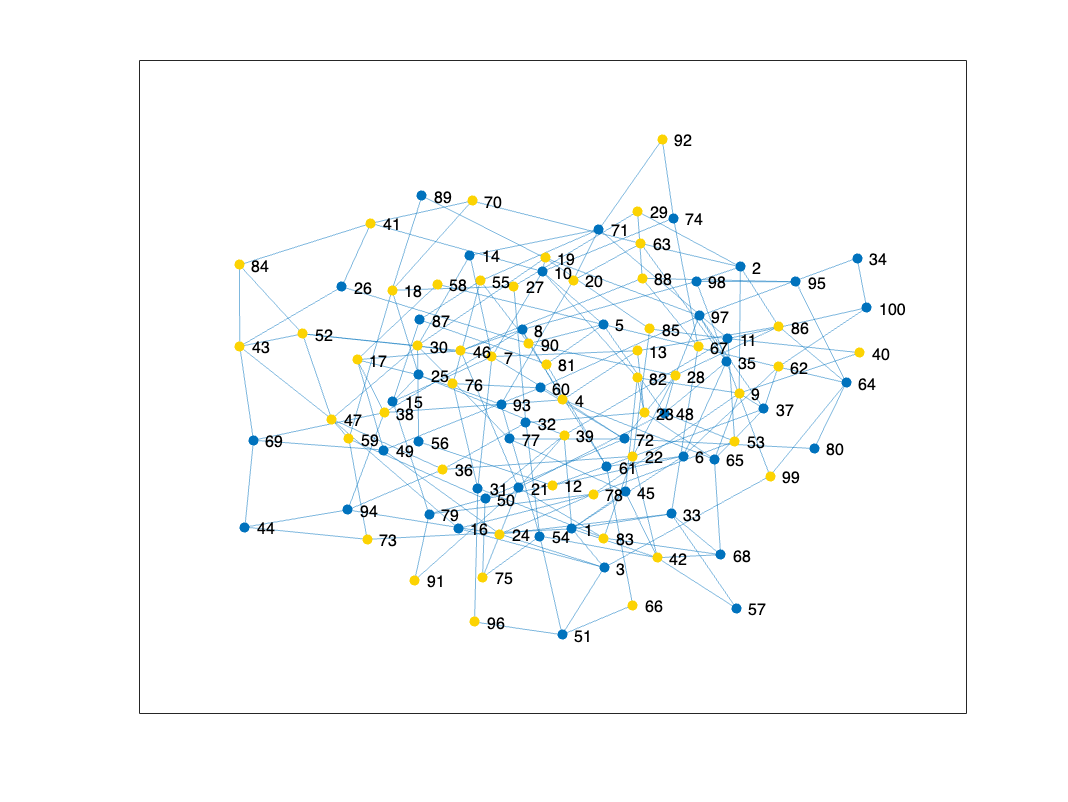

n = 100;            % Number of Nodes
bPercent = 0.5;     % Percent of Nodes that start as Blue Nodes

repititions = 2;    % Number of Repititions after S1
lrAlpha = 0.05;      % Learning Rate of S1
lrBeta = 0.02;       % Learning Rate of repititions after S1
inverseTemp = 0.009;  % Inverse Temperature for SoftMax Function

[nodeConnect,nodePredictions] = makeNetwork(n,bPercent);

% First Trial with Values set above
[updateLogDG,softmaxLogDG] = deGroot(nodeConnect,nodePredictions, n, repititions, lrAlpha, lrBeta, inverseTemp);
[updateLogRL,softmaxLogRL] = reinforced(nodeConnect,nodePredictions, n, repititions, lrAlpha, lrBeta, inverseTemp);
% Second Trial with random values for fun
[updateLogDG2,softmaxLogDG2] = deGroot(nodeConnect,nodePredictions, n, 5, 0.0001, 0.022, 0.005);
[updateLogRL2,softmaxLogRL2] = reinforced(nodeConnect,nodePredictions, n, 5, 0.0001, 0.022, 0.005);

% Some Notes for calling functions:

%   - the final 4 parameters in deGroot and reinforced are hyperparameters
%     and can be changed whenever

%   - the first 2 parameters in deGroot and reinforced MUST be the output 
%     from makeNetwork, the third needs to be the same n used in makeNetwork

%   - in order to change n for a different trial you must recall
%     makeNetwork with the new n before calling deGroot or reinforced

%   - you MUST rename the output between trialsor else it will override the
%     previous one

## Random Network Creation  

function [nodeConnect,nodePredictions] = makeNetwork(n,bPercent)
    nodeConnect = zeros(n);
    
    % Loop for every n
    for i=1:n
        % Get a random number from 2 to 7
        randomLength = randi([2, 7]);
        % Check to see how many neighbors node i already has
        j = sum(sum(nodeConnect(i,:))+sum(nodeConnect(:,i)));
        % While they have less neighbors than their random count:
        while j <= randomLength
            % Choose another random number from 1 to n to be the new neighbor
            randomConnect = randi([1,n]);
            % Check to make sure new neighbor is not themselves
            if randomConnect ~= i
                % Check to make sure they aren't already conncected to new
                % neighbor, that the new neighbor doesn't already have 7
                % neighbors
                if nodeConnect(i,randomConnect) == 1 || sum(nodeConnect(randomConnect,:)) >= 7 || sum(nodeConnect(:,randomConnect)) >= 7
                    % If they are simply restart from the while loop and find a
                    % new random neighbor
                    continue
                else
                    % If all conditions true add new neighbor to i's network
                    nodeConnect(i,randomConnect) = 1;
                    nodeConnect(randomConnect, i) = 1;
                end
            end
            % update j to end loop
            j = sum(sum(nodeConnect(i,:))+sum(nodeConnect(:,i)));
        end
    end

    % Network Creation
    nodePredictions(1:n,1) = 0;
    G = graph(nodeConnect);
    for i=1:n 
        % Generate a random value for each node
        worldView = rand;
        % Place the number of each node's connections in the second column of
        % nodePredictions
        nodePredictions(i,2) = degree(G,i);
        % if the random number is <= the percent of blue we want then assign it
        % a 1 to show that it is assigned blue at initial step
        if worldView <= bPercent
            nodePredictions(i,1) = 1;
        end
    end
    % Create Graph Visual:
    h = plot(G);
    yindicies = find(~nodePredictions);
    highlight(h,yindicies,'NodeColor','#fcd303');
end

## DeGroot

function [updateLog,softmaxLog] = deGroot(nodeConnect,nodePredictions, n, repititions, lrAlpha, lrBeta, inverseTemp)
    % Holds the values of every node through each stage
    updateLog = zeros(n,repititions+2);
    updateLog(:,1) = nodePredictions(:,1);
    softmaxLog = updateLog;
    
    % Needed for indexing updateLog
    currRepitition = 3;
    
    %% S1
    % Loop through all nodes
    for i=1:n
        % find nodes connected to current node
        myNeighbors = find(nodeConnect(i,:));
    
        % Hold the value before it is updated as officially observed
        cummObservation = nodePredictions(i,1);
        % Loop through all connections
        for j=1:length(myNeighbors)
            % set aPE based on observation of Blue or Yellow
            aPE = 1;
            if (nodePredictions(myNeighbors(1,j),1)) ~= aPE
                aPE = -1;
            end
            % New Value = Current Value + alpha * (aPE - Current Valee) 
            cummObservation = cummObservation+(lrAlpha*(aPE-nodePredictions(i,1)));
        end
        updateLog(i,2) = cummObservation/length(myNeighbors);
    end
    
    for i=1:n
        % Soft max and record the observation 1/ 1 + e^(-inverse * observations of Blue)
        softmax = (1/(1+exp(-1*inverseTemp*(updateLog(i,2)))));
        softmaxLog(i,2) = softmax;
        % if softmax value > 0.5 set it blue observation
        if softmax > 0.5
                nodePredictions(i,1) = 1;
            else
                nodePredictions(i,1) = 0;
        end
    end
    % Manually insert S1 into updateLog
    updateLog(:,2) = nodePredictions(:,1);
    
    %% S2 through n
    % Repeat this loop until all repititions are completed
    while repititions > 0
        % loop through all nodes
        for i=1:n
            % Find connections to current nodes
            myNeighbors = find(nodeConnect(i,:));
    
            % Calculate the Total Local Degree
            myTotalConnections = sum(nodePredictions(myNeighbors,2));
    
            % Hold the value before it is updated as officially observed
            cummObservation = nodePredictions(i,1);
    
            % Loop through all connections
            for j=1:length(myNeighbors)
                % Stage s value = previous + beta * RD * aPE
                RD = nodePredictions(myNeighbors(1,j),2)/myTotalConnections;
                aPE = nodePredictions(myNeighbors(1,j),1)-nodePredictions(i,1);
                if aPE ~= 1
                    aPE = -1;
                end
                cummObservation=cummObservation+(lrBeta*RD*aPE);
            end
    
            % Average all the observed values and record 
            updateLog(i,currRepitition) = cummObservation/length(myNeighbors);
        end
        for i=1:n
            % Softmax function = 1/(1+ e ^ (-lambda*Observation)
            softmax = 1/(1+exp(-1*inverseTemp*updateLog(i,currRepitition)));
            softmaxLog(i,currRepitition) = softmax;
            % Update to choosing blue if activated
            if softmax > 0.5
               updateLog(i,currRepitition) = 1;
            else
               updateLog(i,currRepitition) = 0;
            end
        end
        % Set current stage as previous stage for next repitition
        nodePredictions(:,1) = updateLog(:,currRepitition);
    
        % Update repitition counter
        repititions=repititions-1;
        currRepitition = currRepitition+1;
    end
end

## RL

function [updateLog, softmaxLog] = reinforced(nodeConnect,nodePredictions, n, repititions, lrAlpha, lrBeta, inverseTemp)
    % Holds the values of every node through each stage
    updateLog = zeros(n,repititions+2);
    updateLog(:,1) = nodePredictions(:,1);
    softmaxLog = updateLog;
    
    % Needed for indexing updateLog
    currRepitition = 3;
    
    % Loop through all nodes
    for i=1:n
        % find nodes connected to current node
        myNeighbors = find(nodeConnect(i,:));
        % loop through all connections
        for j=1:length(myNeighbors)
            % set aPE based on observation of Blue or Yellow
            aPE = 1;
            if (nodePredictions(myNeighbors(1,j),1)) ~= aPE
                aPE = -1;
            end
            % New Value = Current Value + alpha * (aPE - Current Valee) 
            newValue = nodePredictions(i,1)+(lrAlpha*(aPE-nodePredictions(i,1)));
            %% Softmax Function
            updateLog(i,2) = 1/(1+exp(-1*inverseTemp*newValue));
        end
    end
    % update softmax Log
    softmaxLog(:,2) = updateLog(:,2);
    
    % loop through all value to softmax each node
    for i=1:n
        if updateLog(i,2) > 0.5
            updateLog(i,2) = 1;
        else
            updateLog(i,2) = 0;
        end
    end
    
    % Repeat this loop until all repititions are completed
    while repititions > 0
        % Set all current values to the stored values
        predictionsRound=nodePredictions;
        % loop through all nodes
        for i=1:n
            % Find connections to current nodes
            myNeighbors = find(nodeConnect(i,:));
            % Calculate the Total Local Degree
            totalConnections = sum(nodePredictions(myNeighbors,2));
            % Loop through all connections
            for j=1:length(myNeighbors)
                % Stage s value = previous + beta * RD * aPE
                RD = nodePredictions(myNeighbors(1,j),2)/totalConnections;
                aPE = nodePredictions(myNeighbors(1,j),1)-nodePredictions(i,1);
                if aPE ~= 1
                    aPE = -1;
                end
                predictionsRound(i,1)=predictionsRound(i,1)+(lrBeta*RD*aPE);
            end
        end
        % loop through all value to softmax each node
        for i=1:n
            % Softmax function = 1/(1+ e ^ (-lambda*Observation)
            softmax = 1/(1+exp(-1*inverseTemp*predictionsRound(i,1)));
            softmaxLog(i,currRepitition) = softmax;
            % Update to choosing blue if activated
            if softmax > 0.5
                updateLog(i,currRepitition) = 1;
            end
            % Set current stage as previous stage for next repitition
            nodePredictions(:,1) = updateLog(:,currRepitition);
        end
        % Update repitition counter
        repititions=repititions-1;
        currRepitition = currRepitition+1;
    end
end